%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI 

% This MATLAB script reads CIR (Channel Impulse Response) data from text files,
% processes it, and visualizes both the magnitude and phase of the CIRs.
% The user is prompted to specify the CIR number to display, and the script
% handles data extraction, magnitude calculation, envelope plotting, and
% classification of Line-Of-Sight (LOS) or Non-Line-Of-Sight (NLOS) conditions.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Read files and extract data
file_paths = {'L1_R2_CIRs_Ch_9.txt'};
all_CIR_real_all = {};
all_CIR_imag_all = {};

% Loop through each file and read CIR values
for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

Total number of read CIR pairs for L1_R2_CIRs_Ch_9.txt: 514


disp(['==========================================================================']);               

CIR number 1 for L1_R2_CIRs_Ch_9.txt


Highest sample: 760
Noise variance: 439.0832
Direct path index: 738


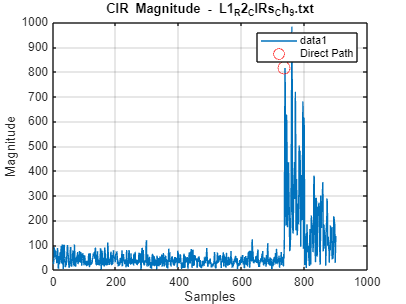

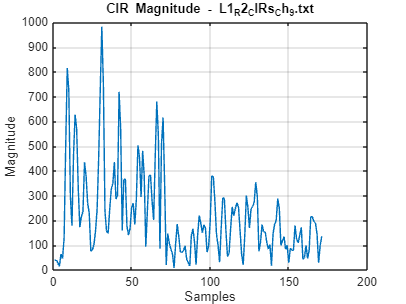

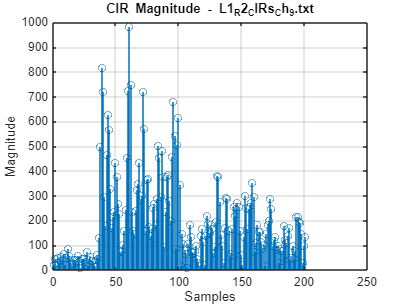

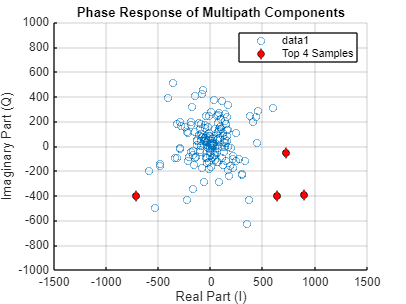

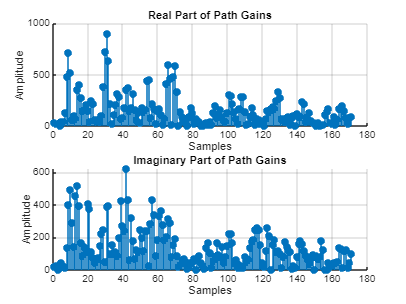


while true
    % Prompt the user for the CIR number to display
    prompt = 'Enter the CIR number you want to display or 0 to exit: ';
    CIRNumber = input(prompt);
    
    if CIRNumber == 0 % To exit, press 0
        break;
    end
    
    if CIRNumber > length(all_CIR_real_all{1})
        disp('The number entered exceeds the available CIR pairs. Please enter a valid number.');
        continue;
    end
    
    for i = 1:length(file_paths)
        file_path = file_paths{i};
        CIR_real_all = all_CIR_real_all{i};
        CIR_imag_all = all_CIR_imag_all{i};

        if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
            disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
            disp(['==========================================================================']);               

            % Calculate the CIR magnitude
            CIR_real = CIR_real_all{CIRNumber}';
            CIR_imag = CIR_imag_all{CIRNumber}';
            CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);

            % Detect the First Path based on the condition
            prompt = 'Enter the condition (LOS (1)/NLOS (0)) for the displayed CIR: ';
            condition = input(prompt, 's');
            if strcmpi(condition, '1')
                directPathIdx = findFirstPathLOS(CIR_magnitude);
            elseif strcmpi(condition, '0')
                directPathIdx = findFirstPathNLOS(CIR_magnitude);
            else
                disp('Invalid condition entered.');
                continue;
            end

            % Display the CIR magnitude
            figure;
            plot(CIR_magnitude);
            title(['CIR Magnitude - ', file_path]);
            xlabel('Samples');
            ylabel('Magnitude');
            grid on;
            
            % Annotate the First Path on the plot
            hold on;
            plot(directPathIdx, CIR_magnitude(directPathIdx), 'ro', 'MarkerSize', 10, 'DisplayName', 'Direct Path');
            legend('show');
            hold off;

            % Display the magnitude of the CIR (from sample 730 onwards)
            figure;
            plot(CIR_magnitude(730:end));
            title(['CIR Magnitude - ', file_path]);
            xlabel('Samples');
            ylabel('Magnitude');
            grid on;

            % Display the magnitude of the CIR (from sample 700 onwards using stem)
            figure;
            stem(CIR_magnitude(700:end));
            title(['CIR Magnitude - ', file_path]);
            xlabel('Samples');
            ylabel('Magnitude');
            grid on;

            % Visualize real vs imaginary parts
            figure;
            scatter(CIR_real(730:end), CIR_imag(730:end));
            xlabel('Real Part (I)');
            ylabel('Imaginary Part (Q)');
            title('Phase Response of Multipath Components');
            axis([-1500 1500 -1000 1000]); % Set x and y axis limits
            grid on;

            % Highlight top 4 samples
            hold on;
            [~, sortedIdx] = sort(CIR_magnitude, 'descend');
            top4Idx = sortedIdx(1:4);
            scatter(CIR_real(top4Idx), CIR_imag(top4Idx), 'd', 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'r', 'DisplayName', 'Top 4 Samples');
            legend;
stdva
            % Visualize the Phase Response of Multipath Components
            figure;
            subplot(2,1,1) % Create the first subplot in a 2x1 grid
            hold on;
            stem(abs(CIR_real(730:end)), 'filled');
            xlabel('Samples');
            ylabel('Amplitude');
            title('Real Part of Path Gains');
            grid on;
            hold off;

            subplot(2,1,2) % Create the second subplot in a 2x1 grid
            hold on;
            stem(abs(CIR_imag(730:end)), 'filled');
            xlabel('Samples');
            ylabel('Amplitude');
            title('Imaginary Part of Path Gains');
            grid on;
            hold off;
            disp(['==========================================================================']);               
        else
            disp(['Invalid CIR number for ', file_path]);
        end
    end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function to detect the First Path for LOS condition
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function directPathIdx = findFirstPathLOS(CIR_magnitude)
    noiseWindow = 720; % Initial window to estimate noise
    magnitudes_in_noise_window = CIR_magnitude(1:noiseWindow);
    
    % Display magnitudes in the noise window
    disp('Magnitudes in the noise window:');
    disp(magnitudes_in_noise_window);
    
    % Calculate the noise variance
    noiseVariance = var(magnitudes_in_noise_window);
    disp(['Noise variance in the window: ', num2str(noiseVariance)]);
    
    % Detect the highest peak
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    % Debugging information
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
   
    thresholdFactor = 3.98; % Factor to detect a significant increase in variance
    threshold = noiseVariance * thresholdFactor;
    
    % Traverse samples after the noise window to detect the increase in variance
    directPathIdx = noiseWindow;
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path index: ', num2str(directPathIdx)]);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function to detect the First Path for NLOS condition
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function directPathIdx = findFirstPathNLOS(CIR_magnitude)
    % Detect the highest peak
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    
    % Estimate noise variance
    noiseWindow = 720; % Initial window to estimate noise
    noiseVariance = var(CIR_magnitude(1:noiseWindow));
    
    % Adjust the threshold based on the LOS variance
    thresholdFactor = 3; % Factor to detect a significant increase in variance
    threshold = noiseVariance * thresholdFactor;
    
    % Initialize the direct path index with the highest peak index
    directPathIdx = highestPeakIndex; 
    
    % Debugging information
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
   
    % Traverse samples after the noise window to detect the increase in variance
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path index: ', num2str(directPathIdx)]); 
end
